# Find Prime Factors Using Shor's Algorithm

This example shows how to apply Shor's algorithm to find the prime factors of a composite number $N$. This algorithm was developed in 1994 by Peter Shor [1], who demonstrated how quantum computers can solve specific problems in polynomial time that would otherwise require more than polynomial time on classical computers.

To find the prime factors $p$ and $q$ of $N$ using Shor's algorithm:

- Choose an integer $a$ in the interval $1<a<N$ that is coprime to $N$.

- Find the period $r$ of the modular exponentiation function $f\left(x\right)=a^x \;\textrm{mod}\;N$, where $r$ is the smallest positive integer that satisfies the congruence $a^r \equiv 1\;\left(\textrm{mod}\;N\right)$.

- Check if $r$ is even and if it satisfies the relation $a^{r/2} \not\equiv -1\;\left(\textrm{mod}\;N\right)$. If both conditions are true, compute the factors of $N$ as $p=\gcd \left(a^{r/2} -1,N\right)$ and $q=\gcd \left(a^{r/2} +1,N\right)$. If either condition is not true, return to step 1 to choose a different value of $a$ until both conditions are satisfied.

The key step in Shor's algorithm is step 2, where quantum computers can find the period of the modular exponentiation function more efficiently than classical computers. On a quantum computer, this step can run in polynomial time with respect to the input size, which is $\log \;N$ bits, while the other steps to find greatest common divisors require only logarithmic time. In contrast, the best-known classical factoring algorithm operates in sub-exponential time.

You can implement step 2 in Shor's algorithm by using a quantum phase estimation circuit with $n$ upper qubits and $m$ lower qubits. The circuit consists of the oracle $U_f$ to handle the modular exponentiation $f\left(x\right)=a^x \;\textrm{mod}\;N$ and the inverse quantum Fourier transform to find the period $r$ from phase estimation, as illustrated in this figure.

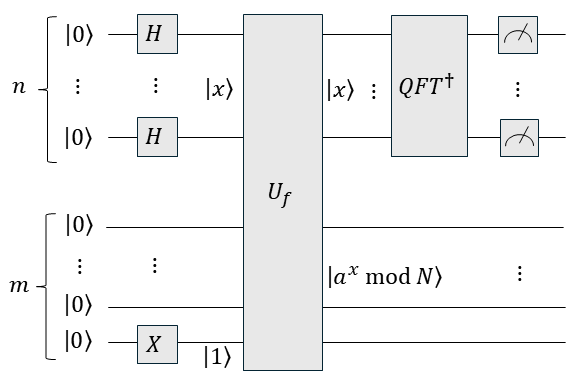

The quantum circuit implementation of the modular exponentiation function is a bottleneck in Shor's algorithm. Often, such circuits require a large number of gates, circuit depth, and qubits, which can lead to significant noise and decoherence in the measurement results. However, there are several approaches for constructing the modular exponentiation function (see [2] and [3]). One approach is to use a specially designed circuit for the modular exponentiation function with specific values of $a$ and $N$, as discussed in [3]. This example shows how to implement these specially designed circuits to find the prime factors of 15, 143, and 247 using local simulation.

## Create Circuit for Modular Exponentiation

You can decompose the modular exponentiation function $f\left(x\right)=a^x \;\textrm{mod}\;N$ into a product

$a^x \;\textrm{mod}\;N=\left(\ldots\left(\left(a^{x_n \cdot 2^0 } \textrm{mod}\;N\right)\times a^{x_{n-1} \cdot 2^1 } \textrm{mod}\;N\right)\times \ldots\right)\times a^{x_1 \cdot 2^{n-1} } \textrm{mod}\;N$,

where 


$$x=x_1 \cdot 2^{n-1} +x_2 \cdot 2^{n-2} +\ldots+x_{n-1} \cdot 2^1 +x_n \cdot 2^0$$


and ${\left∣x\right\rangle}={\left∣x_1 x_2 \ldotsx_n \right\rangle}$ is the binary representation of the variable $x$.

Using this decomposition, the oracle $U_f$ can be broken down into smaller circuits that perform the controlled operations $a^{x_i \;\cdot 2^{n-i} } \;\textrm{mod}\;N$ recursively, where $x_i \;$ is the state of the $i$th control qubit in the upper register. To decompose the oracle into smaller circuits, apply the modular exponentiation operator $U_a {\left∣w\right\rangle}={\left∣w\cdot a\;\left(\textrm{mod}\;N\right)\right\rangle}$ for $2^{n-i}$ times on the state ${\left∣w\right\rangle}$ in the lower register, whose initial state is ${\left∣0\ldots1\right\rangle}$, conditioned on the binary value of $x_i$.

This figure illustrates the oracle $U_f$ for the modular exponentiation $f\left(x\right)=7^x \;\textrm{mod}\;15$, where $n$ upper qubits represent ${\left∣x\right\rangle}$ and $m$ lower qubits represent ${\left∣7^x \;\textrm{mod}\;15\right\rangle}$.

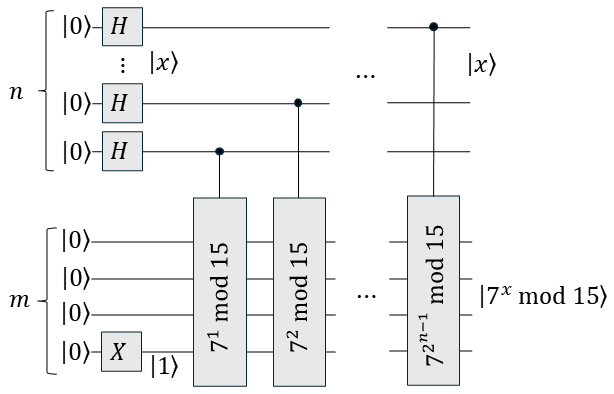

MATLAB® Support Package for Quantum Computing uses a qubit convention that follows most textbooks (see [4]), which is different from the qubit convention in [3]. For a quantum circuit with $n$ qubits, the overall $2^n$ basis states are constructed from the Kronecker product of the $n$ qubit bases, ordered from left to right starting with the lowest-index qubit (topmost in the circuit diagram) to the highest-index qubit (bottommost in the circuit diagram). In other words, if the basis of a single qubit with index $k$ is labeled as ${\left∣q_k \right\rangle}$, which can be ${\left∣0\right\rangle}$ or ${\left∣1\right\rangle}$, then the basis states of the circuit with $n$ qubits are represented by ${\left∣q_1 \right\rangle}\otimes \ldots{\left∣q_k \right\rangle}\otimes \ldots{\left∣q_n \right\rangle}$. For example, for a circuit with two qubits, all possible basis states expressed as a column vector are ${\left∣q_1 q_2 \right\rangle}={\left\lbrack {\left∣00\right\rangle},{\left∣01\right\rangle},{\left∣10\right\rangle},{\left∣11\right\rangle}\right\rbrack }^T$. In contrast, the qubit convention in [3] orders the qubit bases from right to left starting with lowest-index qubit to the highest-index qubit.

Before constructing the oracle $U_f$, first define a function that creates the controlled-swap gate (CSWAP gate or Fredkin gate). Use the `compositeGate` function to construct a composite gate from an inner quantum circuit that performs the controlled-swap operation on an outer circuit. Here, qubit 1 is the control qubit, while qubits 2 and 3 are the target qubits to swap in the inner quantum circuit `gates`. The second input of `compositeGate` defines the mapping of the qubits of the inner circuit to the qubits of the outer circuit. 

function cg = cswapGate(control,target1,target2)
  gates = [cxGate(3,2); ccxGate(1,2,3); cxGate(3,2)];
  cg = compositeGate(gates,[control target1 target2]);
end

Next, define a function that constructs the circuit for the controlled-modular operation $a\;\textrm{mod}\;N$ based on [2] and[3]. In this example, all possible values of $a$ are considered for $N=15$. However, only $a=21$ is considered for $N=143$ and $a=8$ is considered for $N=247$. The first qubit in the inner circuit is set as the control qubit, which is mapped to the $i$th control qubit in the outer circuit that represents the state $x_i$.

function Ua = modexpUnitary(a,N)
% Construct a mod N based on these references:
% [1] Shor, P. https://doi.org/10.48550/arXiv.quant-ph/9508027.
% [2] Markov, I. L., and M. Saeedi. https://doi.org/10.48550/arXiv.1202.6614.
% [3] Tomčala, J. https://doi.org/10.1007/s10773-023-05532-4.
% For N = 15, the values for a are 2, 4, 7, 8, 11, 13.
% For N = 143, only a = 21 is considered.
% For N = 147, only a = 8 is considered.
% Qubit 1 is set as a control qubit, followed by m qubits as targets.

  % For N = 15, see figure 3 of [2]
  if N == 15
    switch a
      case 2
        Ua = [cswapGate(1,2,5); cswapGate(1,2,3); cswapGate(1,3,4)];
      case 4
        Ua = [cswapGate(1,2,4); cswapGate(1,3,5)];
      case 7
        Ua = [cxGate(1,2:5); cswapGate(1,3,4); cswapGate(1,2,3); cswapGate(1,2,5)];
      case 8
        Ua = [cswapGate(1,2,3); cswapGate(1,2,4); cswapGate(1,2,5)];
      case 11
        Ua = [cxGate(1,2:5); cswapGate(1,2,4); cswapGate(1,3,5)];
      case 13
        Ua = [cxGate(1,2:5); cswapGate(1,2,5); cswapGate(1,2,3); cswapGate(1,3,4)];
    end
  end

  % For N = 143, see figure 8 of [3]
  if N == 143
    switch a
      case 21
        Ua = [mcxGate([1 9],5,[]); mcxGate([1 9],7,[]); cxGate(1,5); ...
              mcxGate([1 5],6,[]); mcxGate([1 5],7,[]); mcxGate([1 5],9,[]); ...
              mcxGate([1 5 9],3,[]); mcxGate([1 5 9],4,[]); mcxGate([1 5 9],6,[]); ...
              mcxGate([1 5 9],7,[]); cxGate(1,[5 7]); mcxGate([1 5 6],3,[]); ...
              mcxGate([1 5 6],4,[]); mcxGate([1 7 9],5,[]); mcxGate([1 7 9],6,[]); ...
              cxGate(1,7)];
    end
  end

  % For N = 247, see figure 6 of [3]
  if N == 247
    switch a
      case 8
        Ua = [cswapGate(1,3,6); cswapGate(1,6,9); cswapGate(1,8,9); ccxGate(1,8,5); ...
              cswapGate(1,2,9); mcxGate([1 5 9],2,[]); mcxGate([1 5 9],4,[]); ...
              cswapGate(1,7,9); mcxGate([1 2 4],5,[]); mcxGate([1 7 9],6,[]); ...
              mcxGate([1 6 7],3,[]); mcxGate([1 6 7],4,[]); mcxGate([1 6 8],9,[]); ...
              mcxGate([1 3 5],4,[]); mcxGate([1 2 3],4,[]); mcxGate([1 2 3],5,[]); ...
              mcxGate([1 2 3],6,[]); mcxGate([1 2 3],9,[]); mcxGate([1 7 8],2,[]); ...
              mcxGate([1 7 8],4,[]); mcxGate([1 7 8],6,[]); cxGate(1,8); ...
              mcxGate([1 5 7 8],2,[]); mcxGate([1 5 7 8],3,[]); ...
              mcxGate([1 5 7 8],4,[]); mcxGate([1 5 7 8],6,[]); ...
              mcxGate([1 5 7 8],9,[]); cxGate(1,8:9); mcxGate([1 7 8 9],2,[]); ...
              mcxGate([1 7 8 9],5,[]); mcxGate([1 7 8 9],6,[]); cxGate(1,9); ...
              mcxGate([1 6 7 8],9,[]); cxGate(1,5:6); mcxGate([1 2 3 6],9,[]); ...
              mcxGate([1 5 6 9],2,[]); mcxGate([1 5 6 9],3,[]); cxGate(1,5:6)];
    end
  end
end

To check the modular exponentiation circuit, you can simulate the circuit and confirm that it satisfies the truth tables for specific input states. For example, the truth table for the operation $7\;\textrm{mod}\;15$ applied repeatedly to an initial input of $0001$ is shown in this table.

Use the `modexpUnitary` function to construct the circuit for the controlled-modular operation $7\;\textrm{mod}\;15$. Specify an initial state of $1$ for the control qubit, such that the condition to apply $U_a$ is always true, and initialize the state of the lower $m$ qubits as $0001$. Here, because the $U_a$ operation result can never exceed $N-1$, using $m=4$ qubits is adequate for $N=15$.

N = 15;
a = 7;
m = 4;
Ua = modexpUnitary(a,N);
initState = "1" + string(dec2bin(1,m))

Construct the modular exponentiation circuit to check against the truth table by using `compositeGate` to apply the operation $7\;\textrm{mod}\;15$ recursively. Simulate the output state of this circuit and show the result in binary and decimal representations. The circuit simulation results match the truth tables.

gates = compositeGate(Ua,[1 2:(m+1)]);
c = quantumCircuit(gates);
state = initState;
for k = 1:5
  state = simulate(c,state);
  bitStr = char(formula(state))
  dec = bin2dec(bitStr(end-m:end-1))
end

## Find Prime Factors of 15

Define the composite number $N$ to factor.

N = 15

Define a function that finds the integers $1<a<N$ that are coprime to $N$.

function aList = findCoprime(n)
  aList = [];
  for x = 2:(n-1)
    if gcd(x,n) == 1
      aList(end+1) = x;
    end
  end
end

Choose an integer $a$ from the list of integers that the `findCoprime` function returns. For this example, choose the third integer in the list.

aList = findCoprime(N);
a = aList(3)

Next, define the number of qubits. The first register of the upper qubits $n$ determines the accuracy of the phase estimation. A higher number of these qubits results in a more accurate detection of the period searched, but it also increases the depth of the whole circuit. For this example, choosing $n=4$ is adequate to find the prime factors of 15. The second register of the lower qubits $m$ determines the binary representation of the modular exponentiation $a^x \;\textrm{mod}\;N$, which can be selected using $m=\left\lceil \log_2 \left(N-1\right)\right\rceil$.

n = 4;
m = ceil(log2(N-1));

Construct the oracle $U_f$ that finds the modular exponentiation $f\left(x\right)=a^x \;\textrm{mod}\;N$. Create the modular exponentiation gates for the oracle in a loop, and map their qubits to the qubits of the outer circuit.

UfQPE = [];
for k = 0:n-1
  Ua_2tok = compositeGate(repmat(modexpUnitary(a,N),2^k,1), ...
                          [n-k (n+1):(n+m)]);
  UfQPE = [UfQPE; Ua_2tok];
end

Construct the whole quantum phase estimation circuit. Then plot the circuit.

gates = [hGate(1:n); xGate(n+m)];
gates = [gates; UfQPE; inv(qftGate(1:n))];
c = quantumCircuit(gates);
figure
plot(c)

Simulate the circuit. Show the histogram of the possible states of the upper register with a probability threshold of 0.02.

s = simulate(c);
histogram(s,1:n,Threshold=0.02)

To return these possible states and the probability of measuring each state, use `querystates`. Specify the probability threshold as 0.02. The possible states are returned as binary representations.

[states,probabilities] = querystates(s,1:n,Threshold=0.02);

Convert these binary states into decimal form, which represents the phase estimation.

phase = bin2dec(states)/2^n

Determine the period of the phase using continued fraction or rational fraction approximation. Use the `rat` function and specify the tolerance as 1/2 of the smallest interval spacing between the converted phases, which is $1/2^{n+1}$. The returned values in `den` represent possible values of the period $r$.

[num,den] = rat(phase,1/2^(n+1))

Next, from the denominators of the continued fractions, check if the period $r$ is even and if it satisfies the relation $a^{r/2} \not\equiv -1\;\left(\textrm{mod}\;N\right)$. If both conditions are true, then compute the prime factors of $N$.

found = false;
attempt = 1;
while ~found && attempt <= numel(den)
  r = den(attempt);
  if mod(r,2) == 0 && phase(attempt) ~= 0
      p = gcd(a^(floor(r/2))-1,N);
      q = gcd(a^(floor(r/2))+1,N);
      found = true;
  else
    attempt = attempt + 1;
  end
end
if found == true
  fprintf("Prime factors found: %d and %d \n", p, q);
else
  fprintf("No factors found. Choose different a.")
end

## Find Prime Factors of 143 and 247

Find the prime factors of 143 and 247. Here, the initial guess for $a$ is predetermined based on the specially designed circuit for the modular exponentiation operation, as discussed in [3]. Define a function `findPrimeFactors` that reuses the code in the previous section. Here, choosing $n=7$ is adequate to find the prime factors of 143 and 247.

function [p,q] = findPrimeFactors(N,a)
  n = 7;
  m = ceil(log2(N-1));
  UfQPE = [];
  for k = 0:n-1
    Ua_2tok = compositeGate(repmat(modexpUnitary(a,N),2^k,1), ...
                            [n-k (n+1):(n+m)]);
    UfQPE = [UfQPE; Ua_2tok];
  end
  gates = [hGate(1:n); xGate(n+m)];
  gates = [gates; UfQPE; inv(qftGate(1:n))];
  c = quantumCircuit(gates);
  s = simulate(c);
  [states,probabilities] = querystates(s,1:n,Threshold=0.02);
  phase = bin2dec(states)/2^n;
  [num,den] = rat(phase,1/2^(n+1));
  found = false;
  attempt = 1;
  while ~found && attempt <= numel(den)
    r = den(attempt);
    if mod(r,2) == 0 && phase(attempt) ~= 0
      p = gcd(a^(floor(r/2))-1,N);
      q = gcd(a^(floor(r/2))+1,N);
      found = true;
    else
      attempt = attempt + 1;
    end
  end
  if found == true
    fprintf("Prime factors found: %d and %d \n", p, q);
  else
    p = 1;
    q = N;
    fprintf("No factors found. Choose different a.")
  end
end

Find the prime factors of 143 by choosing $a$ as 21.

[p,q] = findPrimeFactors(143,21)

Find the prime factors of 247 by choosing $a$ as 8.

[p,q] = findPrimeFactors(247,8)

## References

[1] Shor, Peter W. "Polynomial-Time Algorithms for Prime Factorization and Discrete Logarithms on a Quantum Computer." arXiv, January 25, 1996. [https://doi.org/10.48550/arXiv.quant-ph/9508027](https://doi.org/10.48550/arXiv.quant-ph/9508027).

[2] Markov, Igor L., and Mehdi Saeedi. "Constant-Optimized Quantum Circuits for Modular Multiplication and Exponentiation." arXiv, April 2, 2015. [https://doi.org/10.48550/arXiv.1202.6614](https://doi.org/10.48550/arXiv.1202.6614).

[3] Tomčala, J. "On the Various Ways of Quantum Implementation of the Modular Exponentiation Function for Shor's Factorization." International Journal of Theoretical Physics 63, no. 1 (January 10,2024): 14. [https://doi.org/10.1007/s10773-023-05532-4](https://doi.org/10.1007/s10773-023-05532-4).

[4] Singleton Jr, Robert L. "Shor's Factoring Algorithm and Modular Exponentiation Operators." *Quanta* 12, no. 1 (September 15, 2023): 41–130. [https://doi.org/10.12743/quanta.v12i1.235](https://doi.org/10.12743/quanta.v12i1.235).

*Copyright 2024 The MathWorks, Inc.*